# **3D Nonlinear beam-column elements Gravity load analysis followed by transient analysis**

clc; clear;
opsMat = OpenSeesMatlab();
ops = opsMat.opensees;

### Model 

ops.wipe();

% create ModelBuilder (with three-dimensions and 6 DOF/node);
ops.model("BasicBuilder", "-ndm", 3, "-ndf", 6);

% set default units
% ops.defaultUnits("-force", "kip", "-length", "in", "-time", "sec", "-temp", "F");

% Set parameters for model geometry
h = 144.0;  % Story height
by = 240.0;  % Bay width in Y-direction
bx = 240.0;  % Bay width in X-direction

% Create nodes
%       tag    X        Y        Z
ops.node(1, -bx / 2.0, by / 2.0, 0.0);
ops.node(2, bx / 2.0, by / 2.0, 0.0);
ops.node(3, bx / 2.0, -by / 2.0, 0.0);
ops.node(4, -bx / 2.0, -by / 2.0, 0.0);

ops.node(5, -bx / 2.0, by / 2.0, h);
ops.node(6, bx / 2.0, by / 2.0, h);
ops.node(7, bx / 2.0, -by / 2.0, h);
ops.node(8, -bx / 2.0, -by / 2.0, h);

ops.node(10, -bx / 2.0, by / 2.0, 2.0 * h);
ops.node(11, bx / 2.0, by / 2.0, 2.0 * h);
ops.node(12, bx / 2.0, -by / 2.0, 2.0 * h);
ops.node(13, -bx / 2.0, -by / 2.0, 2.0 * h);

ops.node(15, -bx / 2.0, by / 2.0, 3.0 * h);
ops.node(16, bx / 2.0, by / 2.0, 3.0 * h);
ops.node(17, bx / 2.0, -by / 2.0, 3.0 * h);
ops.node(18, -bx / 2.0, -by / 2.0, 3.0 * h);

% Retained nodes for rigid diaphragm
%        tag   X    Y    Z
ops.node(9, 0.0, 0.0, h);
ops.node(14, 0.0, 0.0, 2.0 * h);
ops.node(19, 0.0, 0.0, 3.0 * h);

% Set base constraints
%      tag DX DY DZ RX RY RZ
ops.fix(1, 1, 1, 1, 1, 1, 1);
ops.fix(2, 1, 1, 1, 1, 1, 1);
ops.fix(3, 1, 1, 1, 1, 1, 1);
ops.fix(4, 1, 1, 1, 1, 1, 1);

% Define rigid diaphragm multi-point constraints
%              normalDir retained constrained
ops.rigidDiaphragm(3, 9, 5, 6, 7, 8);
ops.rigidDiaphragm(3, 14, 10, 11, 12, 13);
ops.rigidDiaphragm(3, 19, 15, 16, 17, 18);

% Constraints for rigid diaphragm retained nodes
%      tag DX DY DZ RX RY RZ
ops.fix(9, 0, 0, 1, 1, 1, 0);
ops.fix(14, 0, 0, 1, 1, 1, 0);
ops.fix(19, 0, 0, 1, 1, 1, 0);

fc = 4.0;
Ec = 57000.0 * sqrt(fc * 1000.0) / 1000.0;
% Core concrete (confined);
%                                 tag  f'c   epsc0  f'cu  epscu
ops.uniaxialMaterial("Concrete01", 1, -5.0, -0.005, -3.5, -0.02);

% Cover concrete (unconfined);
%                                 tag  f'c   epsc0  f'cu  epscu
ops.uniaxialMaterial("Concrete01", 2, -fc, -0.002, 0.0, -0.006);

% STEEL
fy = 60.0;  % Yield stress
Es = 30000.0;  % Young's modulus
% Reinforcing steel
%                              tag fy  E0  b
ops.uniaxialMaterial("Steel01", 3, fy, Es, 0.02);

% Column parameters
h = 18.0;
GJ = 1.0e10;
colSec = 1;

% Call the RCsection procedure to generate the column section
%                        id  h  b cover core cover steel nBars barArea nfCoreY nfCoreZ nfCoverY nfCoverZ GJ
RCsection(ops, colSec, h, h, 2.5, 1, 2, 3, 3, 0.79, 8, 8, 10, 10, GJ);

PDelta = "OFF";
% PDelta = "ON";

% Geometric transformation for columns
if PDelta == "OFF"
    ops.geomTransf("Linear", 1, 1.0, 0.0, 0.0);
else
    ops.geomTransf("PDelta", 1, 1.0, 0.0, 0.0);
end

% Number of column integration points (sections);
np = 4;
ops.beamIntegration("Lobatto", colSec, colSec, np);

% Create the nonlinear column elements
eleType = "forceBeamColumn";
%                   tag ndI ndJ transfTag integrationTag
ops.element(eleType, 1, 1, 5, 1, colSec);
ops.element(eleType, 2, 2, 6, 1, colSec);
ops.element(eleType, 3, 3, 7, 1, colSec);
ops.element(eleType, 4, 4, 8, 1, colSec);

ops.element(eleType, 5, 5, 10, 1, colSec);
ops.element(eleType, 6, 6, 11, 1, colSec);
ops.element(eleType, 7, 7, 12, 1, colSec);
ops.element(eleType, 8, 8, 13, 1, colSec);

ops.element(eleType, 9, 10, 15, 1, colSec);
ops.element(eleType, 10, 11, 16, 1, colSec);
ops.element(eleType, 11, 12, 17, 1, colSec);
ops.element(eleType, 12, 13, 18, 1, colSec);

% Define beam ops.elements
% --------------------------
% Define material properties for elastic beams
% Using beam depth of 24 and width of 18
Abeam = 18.0 * 24.0;
% "Cracked" second moments of area
Ibeamzz = 0.5 * 1.0 / 12.0 * 18.0 * (24.0^3);
Ibeamyy = 0.5 * 1.0 / 12.0 * 24.0 * (18.0^3);
beamSec = 2;

% Define elastic section for beams
%                       tag     E    A      Iz       Iy     G    J
ops.section("Elastic", beamSec, Ec, Abeam, Ibeamzz, Ibeamyy, GJ, 1.0);

% Geometric transformation for beams
ops.geomTransf("Linear", 2, 1.0, 1.0, 0.0);

% Number of beam integration points (sections);
np = 3;
ops.beamIntegration("Lobatto", beamSec, beamSec, np);

% Create the beam ops.elements
eleType = "forceBeamColumn";
%                   tag ndI ndJ transfTag integrationTag
ops.element(eleType, 13, 5, 6, 2, beamSec);
ops.element(eleType, 14, 6, 7, 2, beamSec);
ops.element(eleType, 15, 7, 8, 2, beamSec);
ops.element(eleType, 16, 8, 5, 2, beamSec);

ops.element(eleType, 17, 10, 11, 2, beamSec);
ops.element(eleType, 18, 11, 12, 2, beamSec);
ops.element(eleType, 19, 12, 13, 2, beamSec);
ops.element(eleType, 20, 13, 10, 2, beamSec);

ops.element(eleType, 21, 15, 16, 2, beamSec);
ops.element(eleType, 22, 16, 17, 2, beamSec);
ops.element(eleType, 23, 17, 18, 2, beamSec);
ops.element(eleType, 24, 18, 15, 2, beamSec);

DataDir = "output_data";
ops.recorder('Node', '-file', fullfile(DataDir, 'Node18Disp.out'), '-time', '-node', 18, '-dof', 1,2,3, 'disp');
ops.recorder('Node', '-file', fullfile(DataDir, 'Node1React.out'), '-time', '-node', 1, '-dof', 1,2,3, 'reaction');
ops.recorder('Element', '-file', fullfile(DataDir, 'Beam1forceAndDeformation.out'), '-time', '-ele', 1, 'section', 1, 'forceAndDeformation');
% ops.recorder("mpco", "fiber_beams.mpco", "-N",  "displacement", "rotation", "reactionForce", "reactionMoment", "modesOfVibration",...
%     "-E", "force", "section.force", "section.deformation", "section.fiber.stress")

### Plot Model

[OpenSeesMatlab] Model summary
  Nodes: 19
  Beam elements: 24
  MP constraints: 12


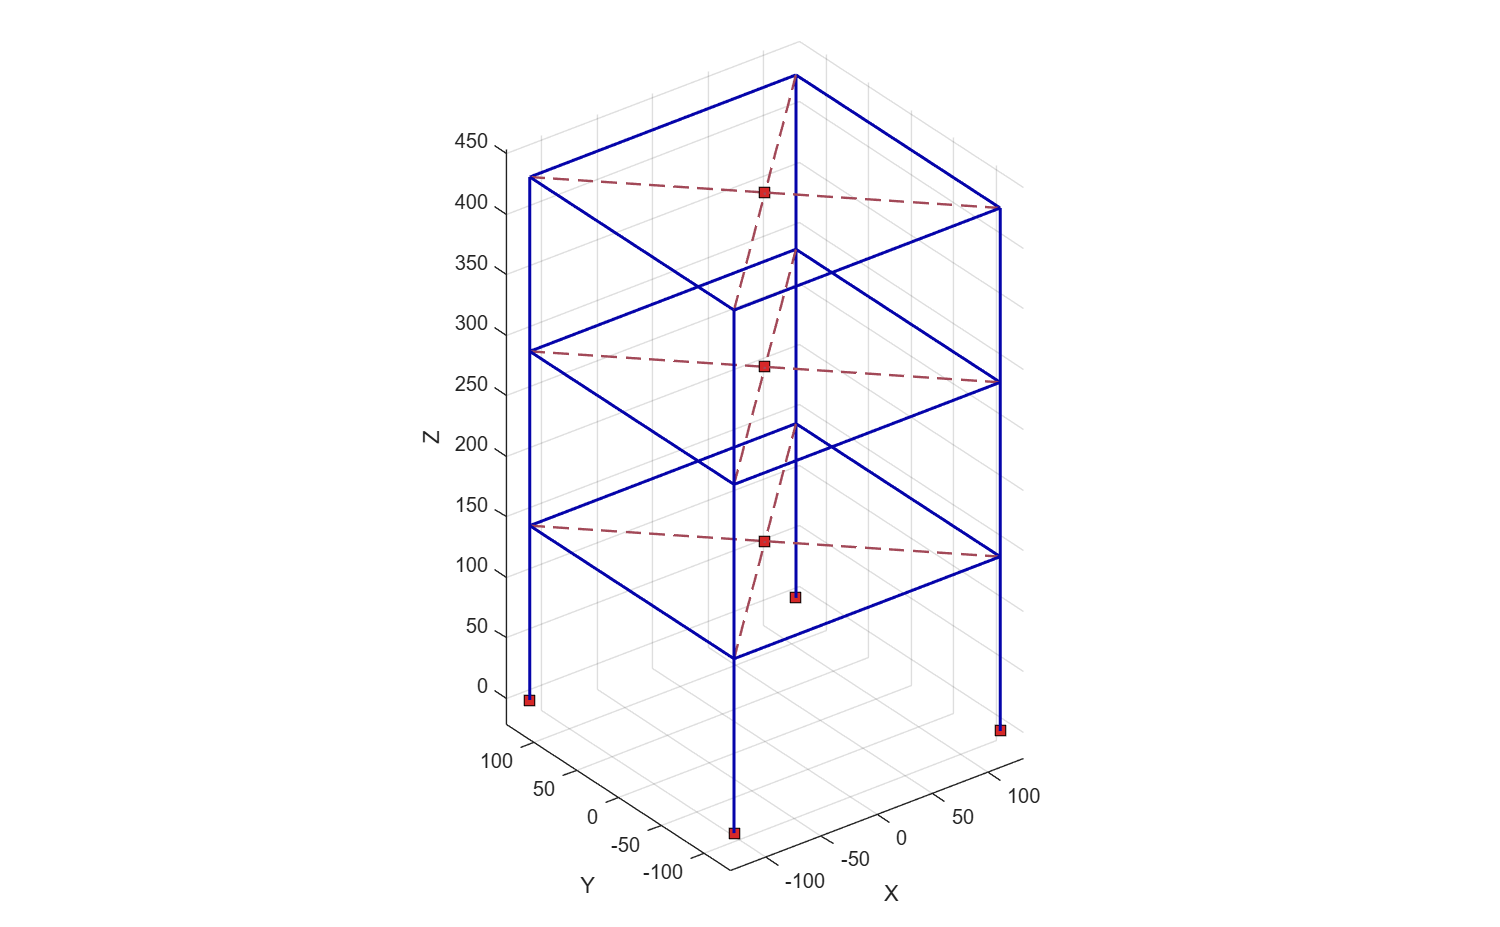

opsMat.vis.plotModel();

### Gravity analysis

% Gravity load applied at each corner node
% 10% of column capacity
p = 0.1 * fc * h * h;
g = 386.09;

% Mass lumped at retained nodes
m = (4.0 * p) / g;

% Rotary inertia of floor about retained node
i = m * (bx * bx + by * by) / 12.0;

% Set mass at the retained nodes
%        tag MX MY MZ   RX   RY   RZ
ops.mass(9, m, m, 0.0, 0.0, 0.0, i);
ops.mass(14, m, m, 0.0, 0.0, 0.0, i);
ops.mass(19, m, m, 0.0, 0.0, 0.0, i);

% Define gravity loads
% create a Constant TimeSeries
ops.timeSeries("Constant", 1);
% create a Plain load pattern
ops.pattern("Plain", 1, 1, "-fact", 1.0);

for i = [5, 6, 7, 8, 10, 11, 12, 13, 15, 16, 17, 18]
    ops.load(i, 0.0, 0.0, -p, 0.0, 0.0, 0.0);
end

[tabasFN.txt](../utils/tabasFN.txt)   

[tabasFP.txt](../utils/tabasFP.txt)

% set rayleigh damping factors
ops.rayleigh(0.0, 0.0, 0.0, 0.0018);

% Define earthquake excitation
% ----------------------------
tabasFN = load("utils/tabasFN.txt");
tabasFP = load("utils/tabasFP.txt");
dt = 0.02;
npts = numel(tabasFN);
% Set up the acceleration records for Tabas fault normal and fault parallel
ops.timeSeries("Path", 2, "-values", tabasFN, "-dt", dt, "-factor", g);
% ops.timeSeries("Path", 3, "-values", tabasFP, "-dt", dt, "-factor", g);
% ops.timeSeries("Path", 2, "-filePath", "utils/tabasFN.txt", "-dt", dt, "-factor", g);
ops.timeSeries("Path", 3, "-filePath", "utils/tabasFP.txt", "-dt", dt, "-factor", g);

% Define the excitation using the Tabas ground motion records
%                         tag dir         accel series args
ops.pattern("UniformExcitation", 2, 1, "-accel", 2);
ops.pattern("UniformExcitation", 3, 2, "-accel", 3);

% create the system of equation
ops.system("UmfPack");
% create the DOF numberer
ops.numberer("Plain");
% create the constraint handler
ops.constraints("Transformation");
% create the convergence test
ops.test("NormDispIncr", 1.0e-6, 100);
% create the solution algorithm, a Newton-Raphson algorithm
ops.algorithm("KrylovNewton");
% create the integration scheme, the Newmark with gamma=0.5 and beta=0.25
ops.integrator("Newmark", 0.5, 0.25);
% create the analysis object
ops.analysis("Transient");

ops.analyze(npts, dt);
ops.wipe();
fprintf("Analysis Done!")

Analysis Done!

### Plot results

Node18Disp = load(fullfile(DataDir, "Node18Disp.out"));
Node1React = load(fullfile(DataDir, "Node1React.out"));
Beam1forceAndDeformation = load(fullfile(DataDir, "Beam1forceAndDeformation.out"));

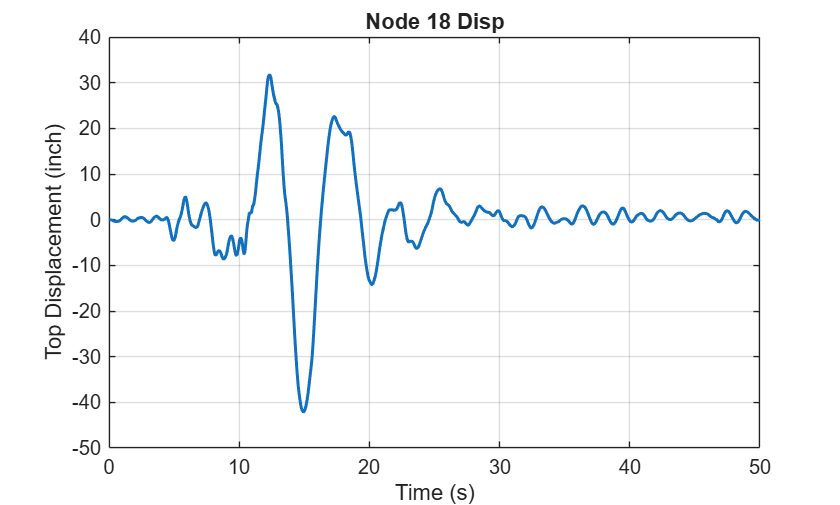

figure;
plot(Node18Disp(:,1), Node18Disp(:,3), 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Top Displacement (inch)');
title('Node 18 Disp');

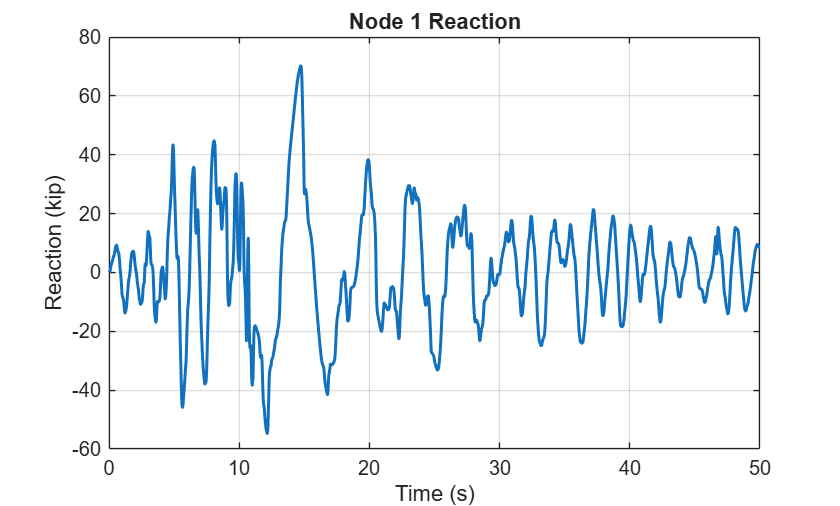

figure;
plot(Node1React(:,1), Node1React(:,3), 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Reaction (kip)');
title('Node 1 Reaction');

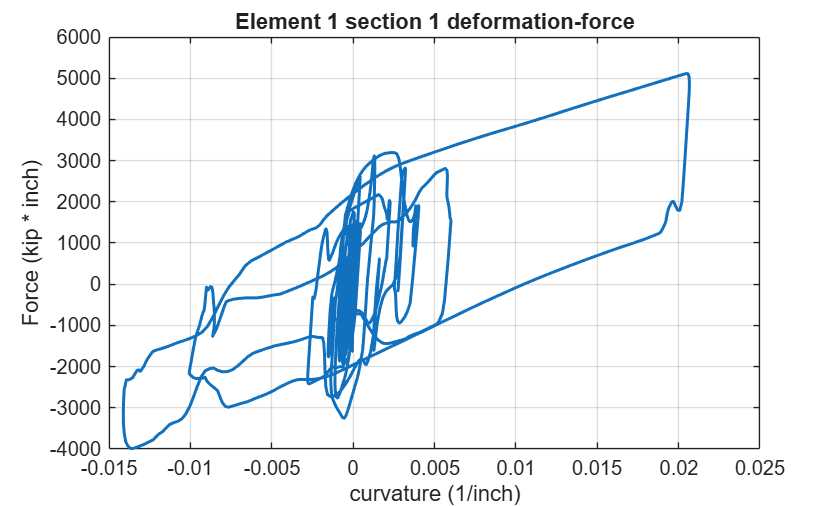

figure;
plot(Beam1forceAndDeformation(:,3), Beam1forceAndDeformation(:,7), 'LineWidth', 1.5);
grid on;
xlabel('curvature (1/inch)');
ylabel('Force (kip * inch)');
title('Element 1 section 1 deformation-force');

### RCSection Function 

function RCsection(ops, id, h, b, cover, coreID, coverID, steelID, ...
    numBars, barArea, nfCoreY, nfCoreZ, nfCoverY, nfCoverZ, GJ)

    % The distance from the section z-axis to the edge of the cover concrete
    % in the positive y direction
    coverY = h / 2.0;

    % The distance from the section y-axis to the edge of the cover concrete
    % in the positive z direction
    coverZ = b / 2.0;

    % Determine the corresponding values from the respective axes to the
    % edge of the core concrete
    coreY = coverY - cover;
    coreZ = coverZ - cover;

    % Define the fiber section
    ops.section('Fiber', id, '-GJ', GJ);

    % Define the core patch
    ops.patch('quad', coreID, nfCoreZ, nfCoreY, ...
        -coreY,  coreZ, ...
        -coreY, -coreZ, ...
         coreY, -coreZ, ...
         coreY,  coreZ);

    % Define the four cover patches
    ops.patch('quad', coverID, 1, nfCoverY, ...
        -coverY,  coverZ, ...
        -coreY,   coreZ, ...
         coreY,   coreZ, ...
         coverY,  coverZ);

    ops.patch('quad', coverID, 1, nfCoverY, ...
        -coreY,  -coreZ, ...
        -coverY, -coverZ, ...
         coverY, -coverZ, ...
         coreY,  -coreZ);

    ops.patch('quad', coverID, nfCoverZ, 1, ...
        -coverY,  coverZ, ...
        -coverY, -coverZ, ...
        -coreY,  -coreZ, ...
        -coreY,   coreZ);

    ops.patch('quad', coverID, nfCoverZ, 1, ...
         coreY,   coreZ, ...
         coreY,  -coreZ, ...
         coverY, -coverZ, ...
         coverY,  coverZ);

    % Define the steel along constant values of y (in the z direction);
    ops.layer('straight', steelID, numBars, barArea, ...
        -coreY, coreZ, -coreY, -coreZ);

    ops.layer('straight', steelID, numBars, barArea, ...
         coreY, coreZ,  coreY, -coreZ);

    % Determine the spacing for the remaining bars in the y direction
    spacingY = (2.0 * coreY) / (numBars - 1);

    % Avoid double counting bars
    numBars = numBars - 2;

    % Define remaining steel in the y direction
    ops.layer('straight', steelID, numBars, barArea, ...
        ( coreY - spacingY),  coreZ, ...
        (-coreY + spacingY),  coreZ);

    ops.layer('straight', steelID, numBars, barArea, ...
        ( coreY - spacingY), -coreZ, ...
        (-coreY + spacingY), -coreZ);

end